% Load your dataset (replace 'your_dataset.csv' with your actual file)
data = readtable('train.csv');
disp(head(data));

       date       store    item    sales
    __________    _____    ____    _____

    2013-01-01      1       1       13  
    2013-01-02      1       1       11  
    2013-01-03      1       1       14  
    2013-01-04      1       1       13  
    2013-01-05      1       1       10  
    2013-01-06      1       1       12  
    2013-01-07      1       1       10  
    2013-01-08      1       1        9  




% Preprocess the data (fill missing values, convert categorical variables, etc.)
% You may need to customize this based on your dataset
% For simplicity, we'll assume the data is already preprocessed.

% Define features and target
features = data{:, {'store', 'item', 'sales'}}; % Replace with your feature names
target = data.sales; % Replace with your target variable name

% Split the data into training and testing sets
rng(42); % For reproducibility
split_ratio = 0.8; % 80% training, 20% testing
split_idx = round(split_ratio * size(features, 1));
train_features = features(1:split_idx, :);
train_target = target(1:split_idx);
test_features = features(split_idx+1:end, :);
test_target = target(split_idx+1:end);

% Train the Random Forest model
num_trees = 100; % You can adjust this based on your needs
model = TreeBagger(num_trees, train_features, train_target, 'Method', 'regression');

% Make predictions on the test set
predictions = predict(model, test_features);

% Evaluate the model
mse = mean((predictions - test_target).^2);
rmse = sqrt(mse);
fprintf('Root Mean Squared Error (RMSE): %.2f\n', rmse);

Root Mean Squared Error (RMSE): 4.87


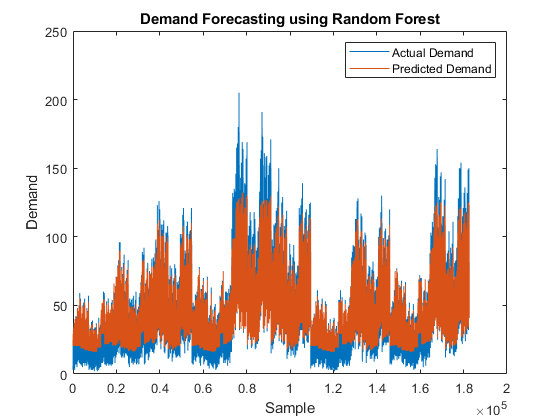


% Visualize the results (optional)
figure;
plot(test_target, 'DisplayName', 'Actual Demand');
hold on;
plot(predictions, 'DisplayName', 'Predicted Demand');
legend('show');
xlabel('Sample');
ylabel('Demand');
title('Demand Forecasting using Random Forest');

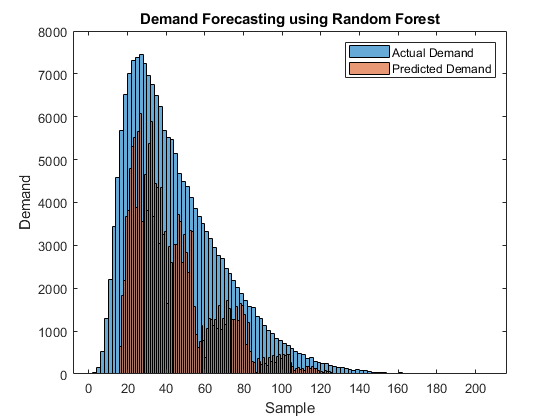

figure;
histogram(test_target, 'DisplayName', 'Actual Demand');
hold on;
histogram(predictions, 'DisplayName', 'Predicted Demand');
legend('show');
xlabel('Sample');
ylabel('Demand');
title('Demand Forecasting using Random Forest');

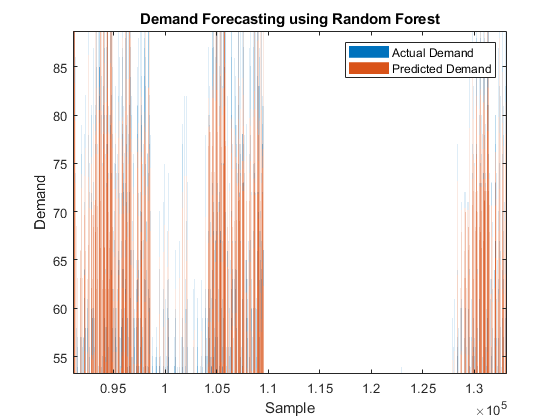

figure;
bar(test_target, 'DisplayName', 'Actual Demand');
hold on;
bar(predictions, 'DisplayName', 'Predicted Demand');
legend('show');
xlabel('Sample');
ylabel('Demand');
title('Demand Forecasting using Random Forest');

xlim([91078 133152])
ylim([53.2 88.7])

Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.